## Задание 4. Выделение краёв.

I = double(im2gray(imread("images/pixel_art_manime.png")))/255;
[height, width, numberOfColorChannels] = size(I);


Создадим матрицу ядра увеличения резкости

edge = reshape([[-1, -1, -1]; ...
                 [-1, 8, -1]; ...
                 [-1, -1, -1]], 3, 3);

Теперь будем сворачивать с изображением

I_EDGE1 = conv2(I, edge); % 1 times
I_EDGE2 = conv2(I_EDGE1, edge); % 2 times
I_EDGE3 = conv2(I_EDGE2, edge); % 3 times

Выведем итоговые изображения...

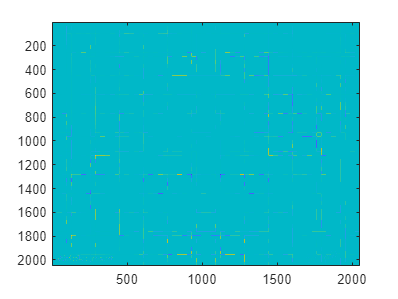

imagesc(I_EDGE1)

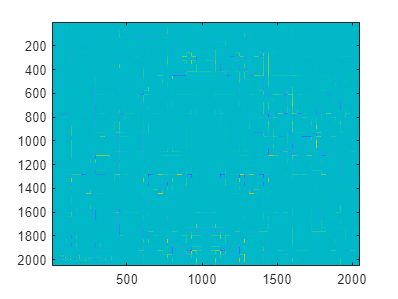

imagesc(I_EDGE2)

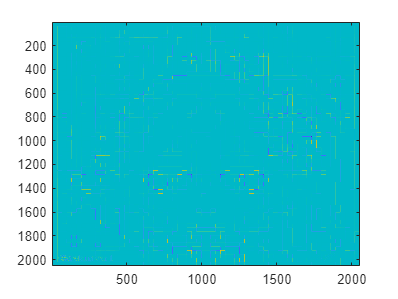

imagesc(I_EDGE3)

Нормируем их по просьбе авторов задания...

I_EDGE1_NORM = I_EDGE1 - min(I_EDGE1(:));
I_EDGE1_NORM = I_EDGE1_NORM ./ max(I_EDGE1_NORM(:))

I_EDGE1_NORM =     0.3577    0.2506    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436
    0.2506    1.0000    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    0.7859    


I_EDGE2_NORM = I_EDGE2 - min(I_EDGE2(:));
I_EDGE2_NORM = I_EDGE2_NORM ./ max(I_EDGE2_NORM(:))

I_EDGE2_NORM =     0.4766    0.5004    0.5361    0.5599    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718    0.5718
    0.5004    0.3577    0.2506    0.1079    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    0.1436    


I_EDGE3_NORM = I_EDGE3 - min(I_EDGE3(:));
I_EDGE3_NORM = I_EDGE3_NORM ./ max(I_EDGE3_NORM(:))

I_EDGE3_NORM =     0.4636    0.4599    0.4526    0.4441    0.4368    0.4332    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320    0.4320
    0.4599    0.4782    0.5147    0.5791    0.6156    0.6339    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    0.6290    

Сохраним, чтобы посмотреть на то насколько выделились края изображения... (заметно ли?)

imwrite(I_EDGE1, 'pixel_art_EDGE1.png');
imwrite(I_EDGE2, 'pixel_art_EDGE2.png');
imwrite(I_EDGE3, 'pixel_art_EDGE3.png');

imwrite(I_EDGE1_NORM, 'pixel_art_EDGE4.png');
imwrite(I_EDGE2_NORM, 'pixel_art_EDGE5.png');
imwrite(I_EDGE3_NORM, 'pixel_art_EDGE6.png');

Теперь переходим к анализу Фурье-образов...

*Найдите Фурье-образ от исходного изображения и от каждого из ядер, заполнив пропуски нулями....*

Теперь мы нашли Фурье-образ оригинала и каждого из ядер - перемножим их поэлементно и проверим истинность теоремы о Свёртке...

I_FFT =  (fft2(I)); 
EDGE_FFT = (fft2(edge, height, width));

*Так как операция свёртки - ассоциативна, то можно также и расширить теорему о свёртке - если будем перемножать образы несколько раз, то и свёртка будет применяться не один раз, взгляните просто ниже:*

I_EDGE1 = I_FFT.*EDGE_FFT; 
I_EDGE2 = I_FFT.*EDGE_FFT.*EDGE_FFT; 
I_EDGE3 = I_FFT.*EDGE_FFT.*EDGE_FFT.*EDGE_FFT; 

Не забудем выполнить обратное преобразование Фурье

I_EDGE1 = ifft2(I_EDGE1);
I_EDGE2 = ifft2(I_EDGE2);
I_EDGE3 = ifft2(I_EDGE3);

Теперь сохраняем ново-полученные изображения, чтобы сравнить...

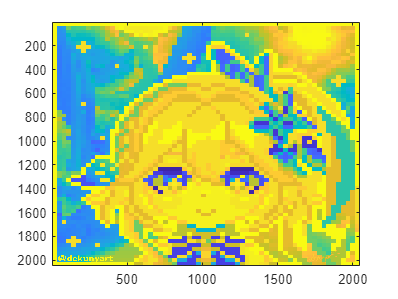

imagesc(I)


imwrite(I_EDGE1, 'pixel_art2_EDGE1.png');
imwrite(I_EDGE2, 'pixel_art2_EDGE2.png');
imwrite(I_EDGE3, 'pixel_art2_EDGE3.png');